%% 9번 문제
clear; clc;

rng('default');
num_products = 50000;

% (a) 
pass_1 = rand(num_products, 1) <= 0.94;

% (b)
pass_2 = false(num_products, 1); % 우선 전체 false 초기화
idx_step2 = find(pass_1); % 1단계 통과한 제품들의 인덱스
pass_2(idx_step2) = rand(length(idx_step2), 1) <= 0.91;

% (c)
pass_3 = false(num_products, 1); % 전체 false 초기화
idx_step3 = find(pass_2); % 2단계까지 최종 통과한 제품들의 인덱스
pass_3(idx_step3) = rand(length(idx_step3), 1) <= 0.88;

% (d) 
% 최종 합격은 3단계까지 모두 패스(pass_3 == true)한 제품
final_pass_rate = mean(pass_3);
fprintf('=== 9번 결과 ===\n');

=== 9번 결과 ===


fprintf('최종 합격률: %.2f%%\n', final_pass_rate * 100);

최종 합격률: 75.16%


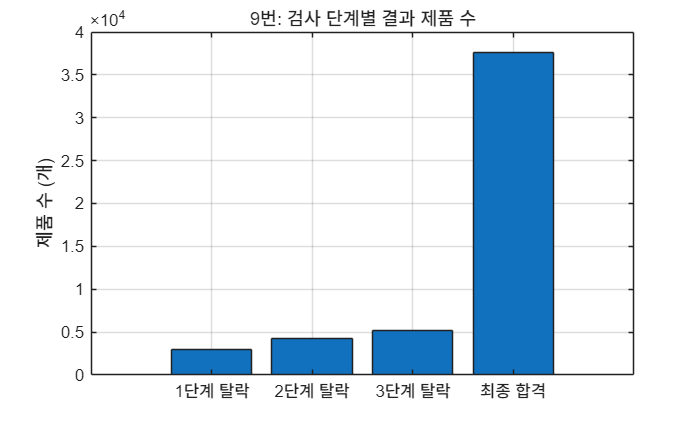


% (e) 
fail_step1 = num_products - sum(pass_1);                 % 1단계 탈락
fail_step2 = sum(pass_1) - sum(pass_2);                 % 2단계 탈락
fail_step3 = sum(pass_2) - sum(pass_3);                 % 3단계 탈락
final_passed_count = sum(pass_3);                       % 최종 합격

chart_data = [fail_step1, fail_step2, fail_step3, final_passed_count];
labels = {'1단계 탈락', '2단계 탈락', '3단계 탈락', '최종 합격'};

figure(10);
bar(chart_data);
set(gca, 'XTickLabel', labels);
title('9번: 검사 단계별 결과 제품 수');
ylabel('제품 수 (개)');
grid on;